clear
close all
clc
addpath 'C:\GitHub\CVUT-MatLab\grant\functions\'

## Sections

outRadius = ones(6,1)*40*10^-3;
inRadius = outRadius - 5*10^-3;

for j = 1:size(outRadius,1)
    sections.A(j,1) = outRadius(j)^2*pi() - inRadius(j)^2*pi() ;
    sections.Iy(j,1) = pi() * outRadius(j) ^ 4 / 4 - pi() * inRadius(j) ^ 4 / 4  ;
end


sections.Iz = sections.Iy;
sections.Ix = sections.Iy*2;
sections.E  = ones(size(outRadius,1),1) * 210*10^9;
sections.v  = ones(size(outRadius,1),1) * 0.3;

ndisc = 16;


## Nodes

nodes.x = [0;2;0;2;4];                          % x coordinates of nodes
nodes.y = [0;0;0;0;0];                          % y coordinates of nodes
nodes.z = [0;0;2;2;2];                          % z coordinates of nodes
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1;3];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;3];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;3];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [];                    % node indices with restricted x-direction displacements
kinematic.ry.nodes = [];                   % node indices with restricted y-direction displacements
kinematic.rz.nodes = [1;3];                    % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

beams.nodesHead = [1;3;3;2;4;2];   % elements starting nodes
beams.nodesEnd  = [2;2;4;4;5;5];   % elements ending nodes
nr = numel(beams.nodesHead);

### Beams sections

beams.disc      = ones(nr,1)*ndisc;
beams.sections  = 1:size(outRadius,1);

ng = max(max(beams.sections));
plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % to avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % to avoid tight limits
zlim([min(nodes.z)-0.1,max(nodes.z)+0.1]);  % to avoid tight limits
grid on


## Loads

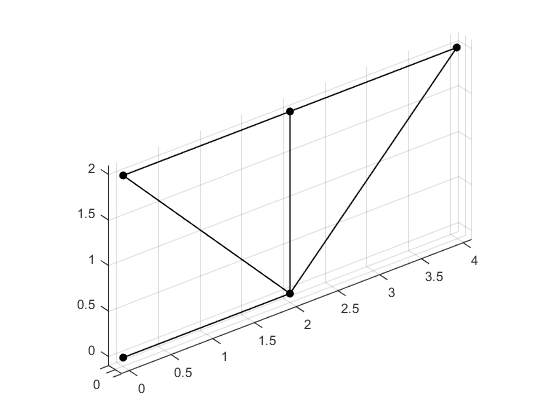

loads.y.nodes = [];           % node indices with x-direction forces
loads.y.value = [];           % magnitude of the x-direction forces
loads.x.nodes = [];           % node indices with y-direction forces
loads.x.value = [];           % magnitude of the y-direction forces 
loads.z.nodes = [5];           % node indices with y-direction forces
loads.z.value = [-1000];           % magnitude of the y-direction forces 

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 
hold off;

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoBeamsFn(beams);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



### Linear analysis 

#### Frames

endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = endForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);

#### Truss

trussCond = true;
if trussCond   
    trusses = beams;
    nodes.ndofs = sum(sum(nodes.dofs));
    nodes.nnodes    = nnodes;
    
    kinematic.x.nodes = [1;3];              % node indices with restricted x-direction displacements
    kinematic.y.nodes = [1;3;2;4;5];              % node indices with restricted y-direction displacements
    kinematic.z.nodes = [1;3];              % node indices with restricted z-direction displacements
    
    nodes.dofs = true(nnodes,3);                % no kinematic boundary conditions
    nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
    nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
    nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
    
    loads.y.nodes = [];           % node indices with x-direction forces
    loads.y.value = [];           % magnitude of the x-direction forces
    loads.x.nodes = [];           % node indices with y-direction forces
    loads.x.value = [];           % magnitude of the y-direction forces 
    loads.z.nodes = [5];           % node indices with y-direction forces
    loads.z.value = [-1000];           % magnitude of the y-direction forces 
    
    dofs = true(nnodes,3);                % no kinematic boundary conditions
    dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
    dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
    dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
    dofs = reshape(dofs.',[],1);
    nd = sum(dofs,"all");
    
    trusses.sections  = sections;
    trusses.nbeams  = nr;
    trusses.vertex = beamVertexFn(trusses,nodes);
    trusses.codeNumbers = codeNumbersFn(trusses,nodes);
    trusses.XY = XYtoBeamsFn(trusses);
    trusses.disc = 1;
    trusses.ndofs = max(max(trusses.codeNumbers));
    forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                         1, ...
                         [loads.x.value; loads.y.value; loads.z.value ], ...
                         nnodes*3, 1);
    f = forceVector(reshape(dofs.', 1, [])');
    
    F.global = sparse(trusses.ndofs,1);
    F.global(1:max(max(trusses.codeNumbers))) = f;
    
    Tcell = trussMatrixTFn(trusses);
    
    K = trussMatrixKFn(trusses,Tcell);
    [F.local,~] = vectorFFn(K,F,Tcell,trusses);

    endForces.local = sparse(7*ones(elements.nelement,1),1:elements.nelement,repmat(F.local(4,:), ndisc, 1),12,ndisc*nr);
end

### Non-linear analysis

geometricMatrix = geometricMatrixFn(elements,transformationMatrix,endForces);

volume = sum(elements.sections.A .* transformationMatrix.lengths);
Results = criticalLoadFn(stiffnesMatrix,geometricMatrix,10);

[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

disp('1. kritické břemeno')

1. kritické břemeno


disp([num2str(sortedValues(1)),' N'])

83.0901 N


disp('2. kritické břemeno')

2. kritické břemeno


disp([num2str(sortedValues(2)),' N'])

-214.6954 N


for i = 1:nr
    idR = 1:12;
    idC = (i-1)*ndisc + 1 : i*ndisc;
    % Vytvoření podmatice
    endForces.beams{i} = endForces.local(idR, idC);
    N(1,i)=endForces.beams{i}(7,1);
end
N = full(N'/1000)

N =    -2.0000
    1.4142
    1.0000
    0.0000
    1.0000
   -1.4142
